clear
close all

load chirp

Original sound

% Fs = 44100;
% y = sweeptone(2,1,Fs);

t = linspace(0,1,numel(y))*(numel(y)-1)/Fs;
sound(y,Fs)


Delay filter

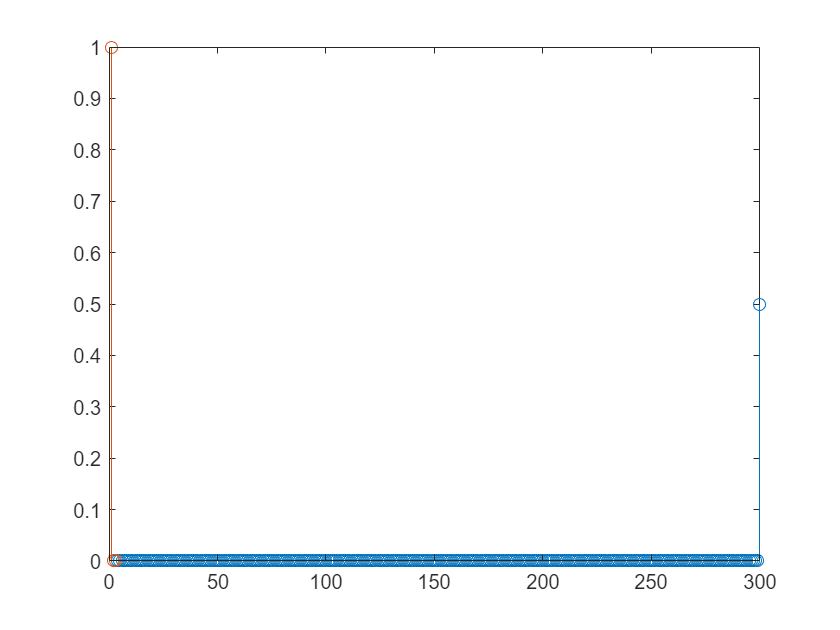

b = [1, 0, 0];

n = 300;
% a = exp(-1:-1:-n)
a = zeros(n,1);
a(1) = 1;
a(n) = 0.5;

stem(a)
hold on
stem(b)
hold off


yfilt = filter(b,a,y);

sound(yfilt,Fs)

Show the impulse response

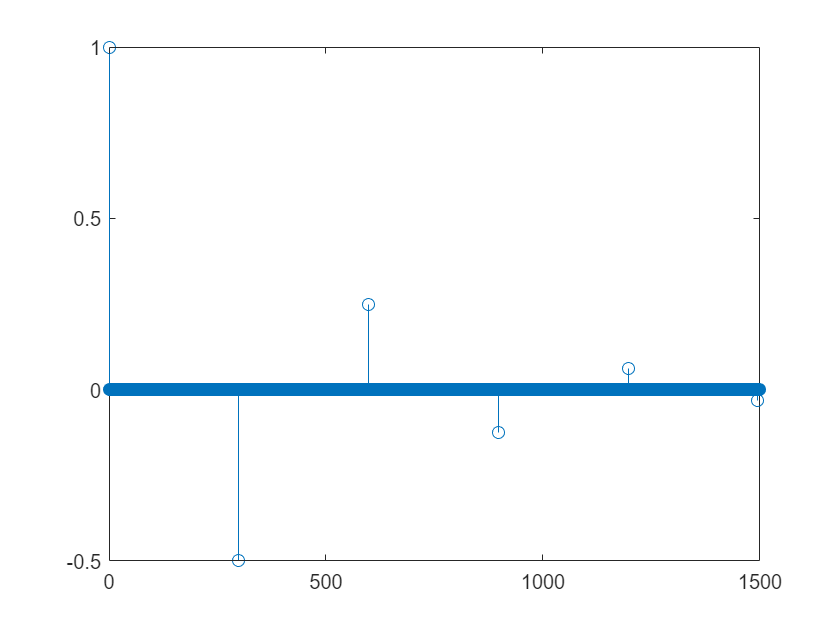

[h,t_h] = impz(b,a,n*5);

stem(t_h,h)

First, create a data object for the System Identification Toolbox

Ts = 1/Fs;
data = iddata(yfilt,y,Ts);

Now estimate the impulse response

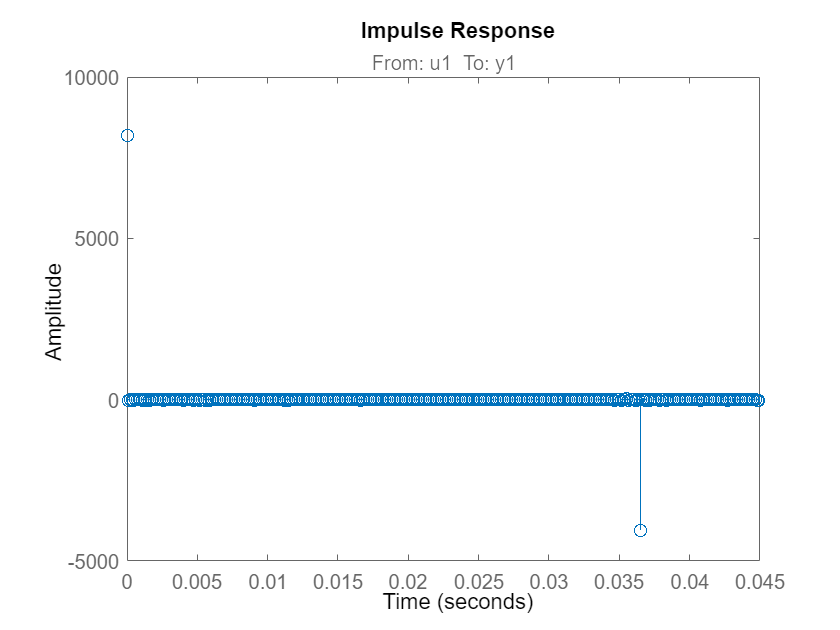

model = impulseest(data,820);

h = impulseplot(model);
showConfidence(h);

Here are the coefficients (so that they could be reused as a filter)

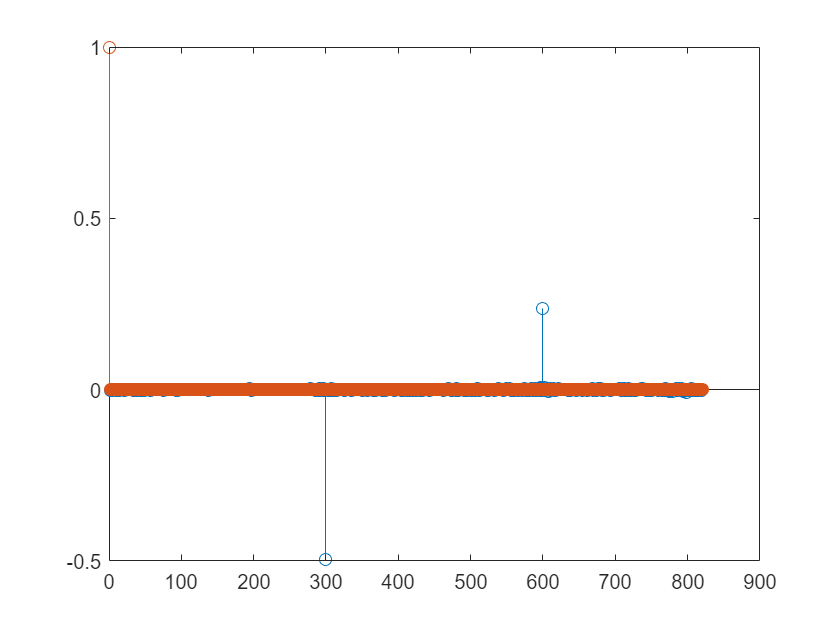

tfModel = tf(model);
stem(tfModel.num{1})
hold on
stem(tfModel.denom{1})
hold off

Here's a comparison of the filtered signals using the original filter and the derived filter

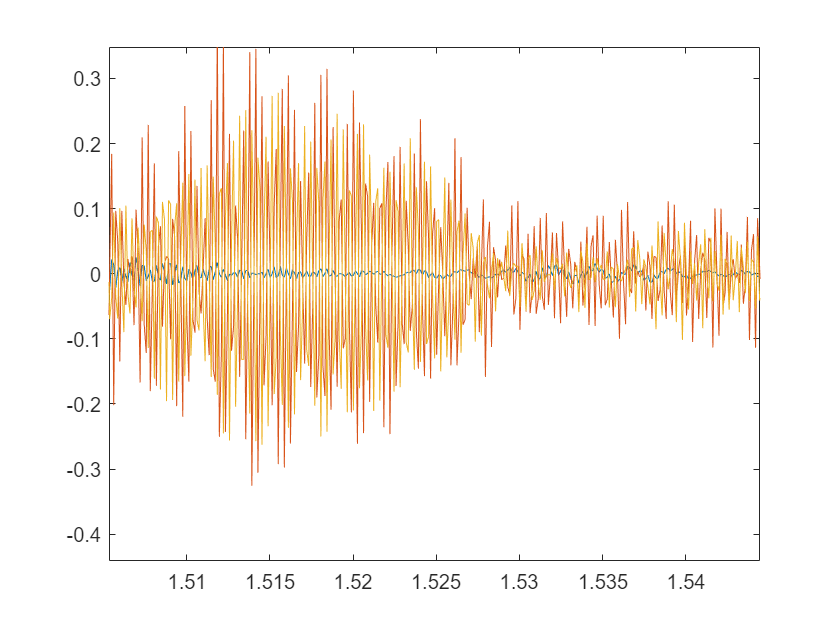

aEst = tfModel.num{1};
bEst = tfModel.denom{1};
yFiltEstimated = filter(bEst,aEst,y);

plot(t,y,t,yfilt,t,yFiltEstimated)

sound(yfilt,Fs)

sound(yFiltEstimated,Fs)
